% Package orientation: Runnable validation or benchmark wrapper. It loads saved models or constructs small checks, then reports metrics/diagnostics without changing training code.

% TEST_GPU_implementation_dynamical_systems_vanderpol_full_rank6k.mlx
% Load a saved trained network and evaluate vanderpol full-rank 6k trajectory performance.
% This script does not train. Run the matching training script first, then choose which saved backend to load below.

clear; clc;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);
clear snn_plot_dynamics_test_trajectories snn_plot_dynamics_sections_and_return_maps plot_closed_loop_validation_trajectories; % Reload normalized-coordinate plotting helpers.

%% ---------------- Saved Network ----------------
% The saved file stores the training options and best trained bias vector.
% The test action reconstructs deterministic weights, restores best.B, and
% evaluates closed-loop trajectories generated from the saved options.
test_seeds = [1]; % Trained initialization seed(s) to evaluate.
diagnostic_seed_index = 1; % Spike diagnostics use one representative seed to keep live plots readable.
test_backend = 'gpu'; % This script evaluates with the GPU implementation.
trained_model_backend = 'gpu'; % Use the model family produced by the matching training script.
[model_files, model_file, trained_model_backend] = snn_resolve_seed_model_files(repo_root, 'dynamical_systems_vanderpol_full_rank6k', test_backend, test_seeds, diagnostic_seed_index, trained_model_backend);
save_diagnostic_files = false;  % set true to write diagnostic artifacts as well as displaying inline
diag_dir = fullfile(repo_root, 'outputs', 'diagnostics', sprintf('dynamical_systems_vanderpol_full_rank6k_trained_%s_test_gpu', trained_model_backend));
if save_diagnostic_files && exist(diag_dir, 'dir') ~= 7, mkdir(diag_dir); end
missing_model_files = model_files(cellfun(@(f) exist(f, 'file') ~= 2, model_files));
if ~isempty(missing_model_files)
    error('Saved model(s) not found. Run the matching training script for all requested seeds first. First missing file: %s', missing_model_files{1});
end

%% ---------------- Evaluation Overrides ----------------
% model_file is required. Add fields here only when you intentionally want to
% override saved options for evaluation, for example a shorter test duration.
closed_loop_test_time = single(50); % Closed-loop rollout duration in dynamical-system time units.
closed_loop_test_warmup_time = single(5); % Network-only autonomous warmup before the scored comparison.
closed_loop_test_ics = 5; % Number of test initial conditions to evaluate.
closed_loop_test_ic_seed = 123; % Random seed controlling deterministic test initial-condition jitter.
min_peak_prominence = 1; % Minimum peak prominence used for peak return-map plots.

opts = struct();
opts.model_files = model_files;
opts.seed_list = test_seeds;
opts.model_file = model_file; % Representative seed retained for diagnostics and legacy plot helpers.
opts.closed_loop_test_time = closed_loop_test_time;
opts.closed_loop_test_warmup_time = closed_loop_test_warmup_time;
opts.closed_loop_test_ics = closed_loop_test_ics;

opts.closed_loop_test_ic_seed = closed_loop_test_ic_seed;
%% ---------------- Run Trajectory Test ----------------
% result.test.loss is mean closed-loop trajectory loss.
% result.test.Z contains generated output trajectories when available.
result = snn_primary_api('test_dynamics', 'dynamical_systems', test_backend, opts);

[SEED AUDIT] Single seed tested; no pairwise network-difference check required.


Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\dynamical_systems_vanderpol_full_rank6k_gpu_test_analysis_20260713_175111_183.mat


fprintf('Testing with %s backend; loaded %s-trained networks for seeds [%s]. Diagnostic seed file:\n%s\n', test_backend, trained_model_backend, num2str(test_seeds), model_file);

Testing with gpu backend; loaded gpu-trained networks for seeds [1]. Diagnostic seed file:
C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\models\dynamical_systems_vanderpol_full_rank6k_gpu_primary_seed001.mat


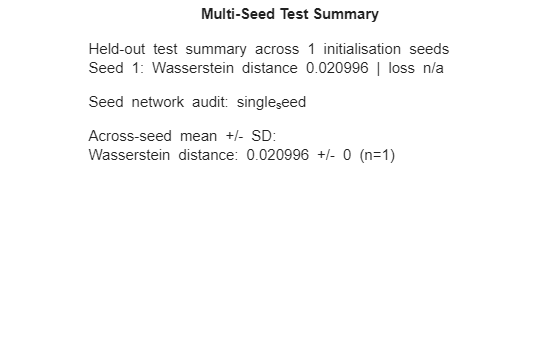

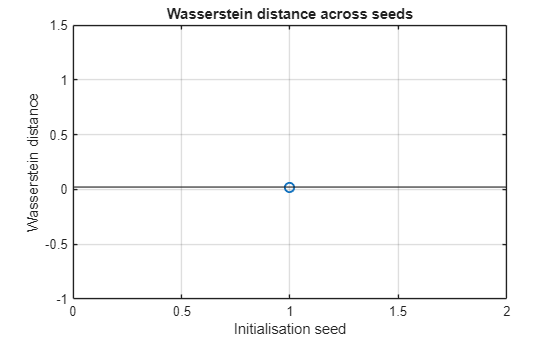

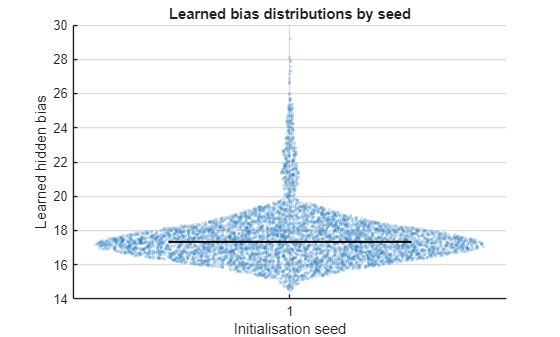

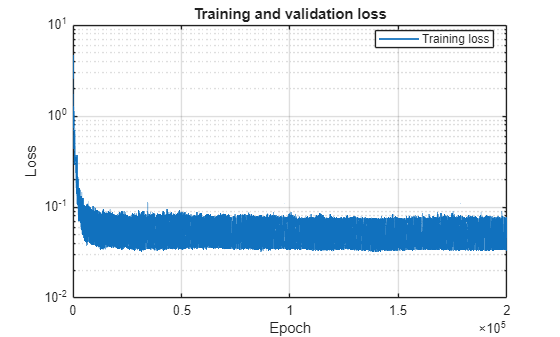

snn_plot_test_result(result);

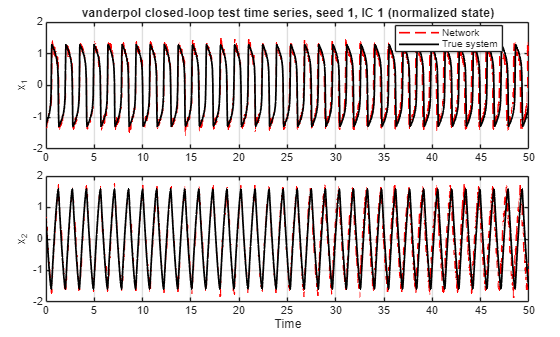

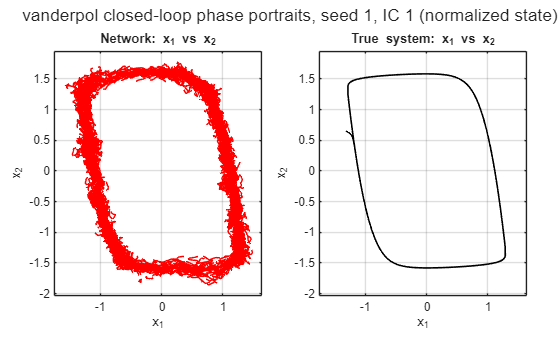

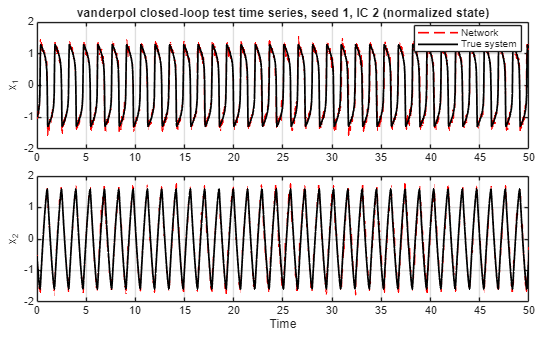

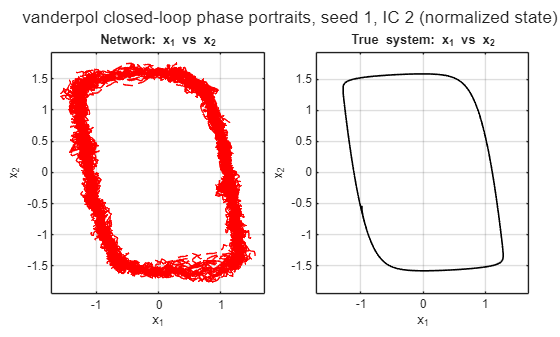

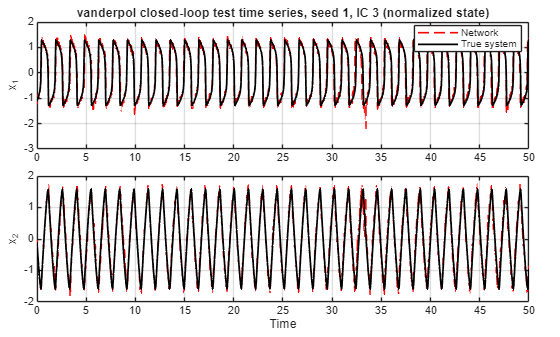

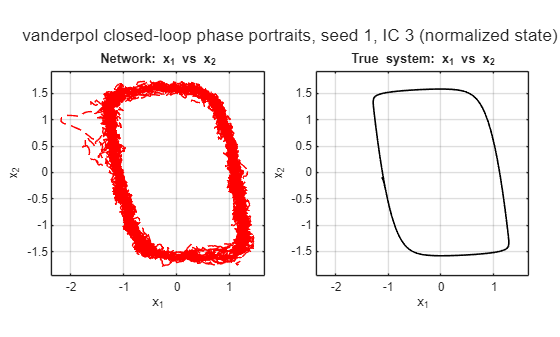

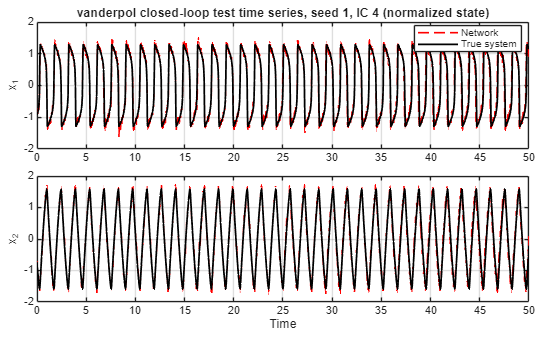

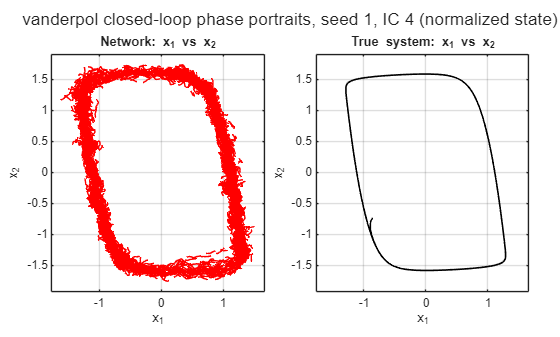

snn_plot_dynamics_test_trajectories(result);

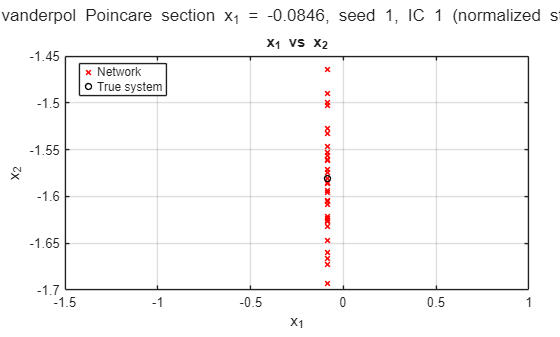

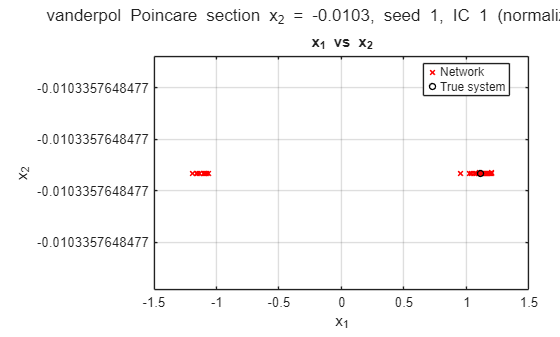

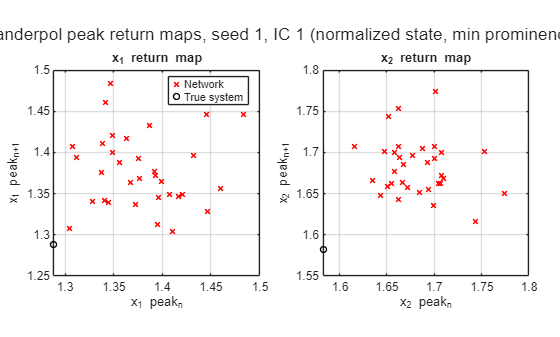

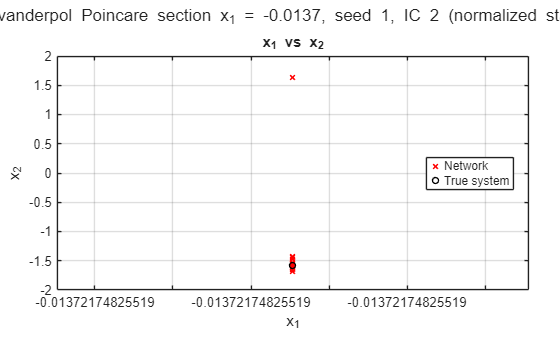

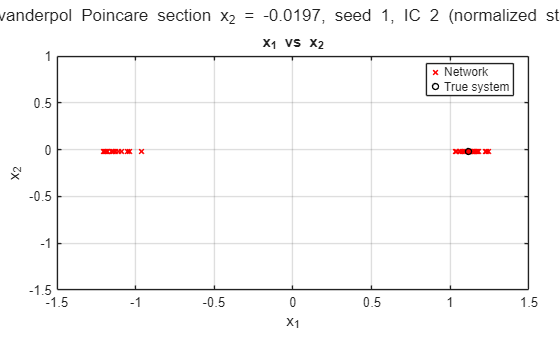

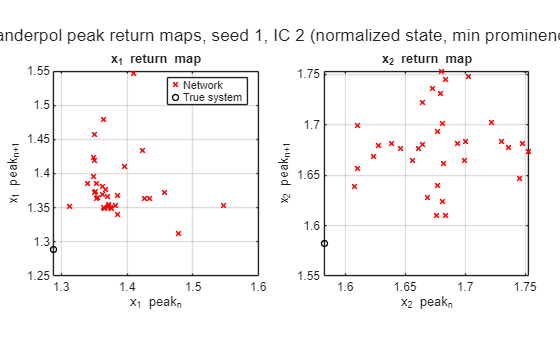

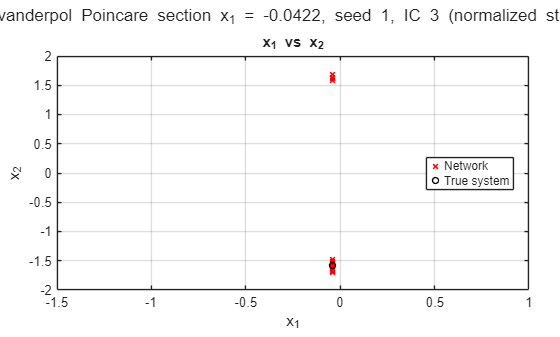

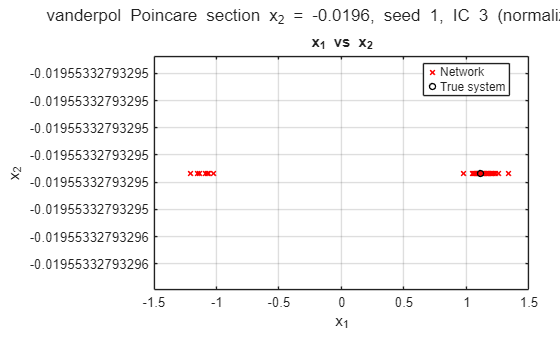


snn_plot_dynamics_sections_and_return_maps(result, '', min_peak_prominence);


=== Spiking Diagnostics: vanderpol_test_dynamics ===
Samples: 1 | Neurons: 6000 | Steps/sample: 5000 | Seconds/sample: 5
Mean neuron firing rate: 0.6756 Hz | median 0 Hz | 95th percentile 4.6 Hz
Active neurons: 2731 / 6000 (45.52%)
Silent neurons: 3269 / 6000 (54.48%)
Mean population rate by sample: 0.6756 Hz/neuron
Mean active neurons by sample: 45.52% | silent 54.48%
Total within-sample ISIs counted: 17537
Median per-neuron mean inverse-ISI rate: 2.74065 Hz


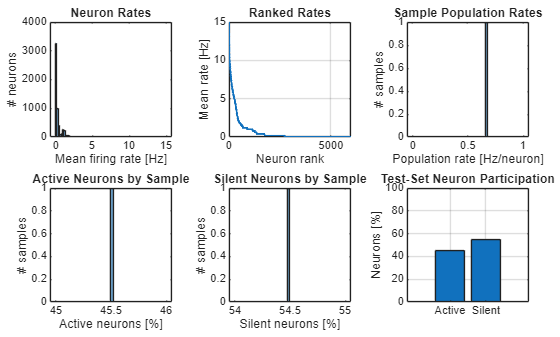

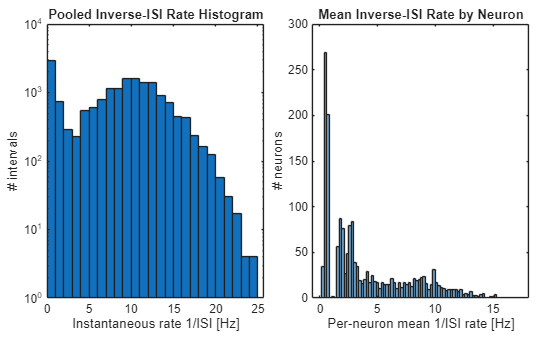

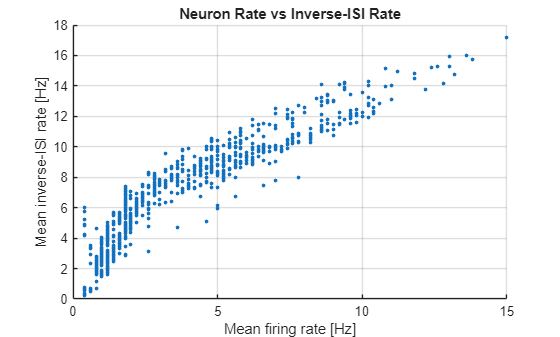

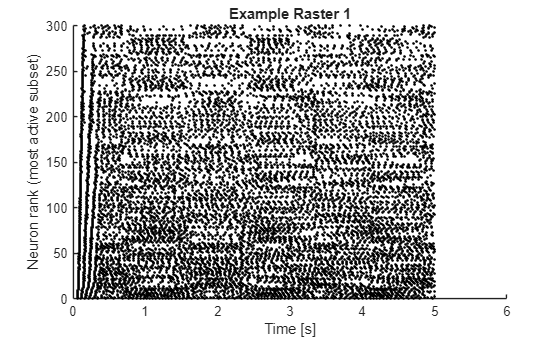

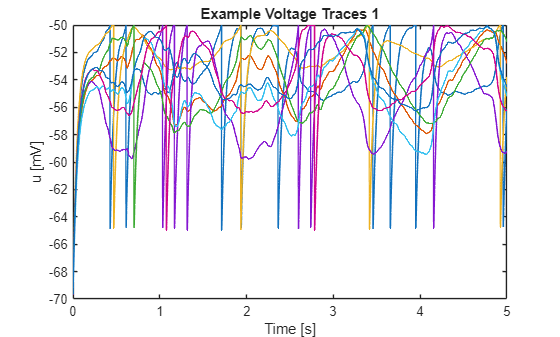

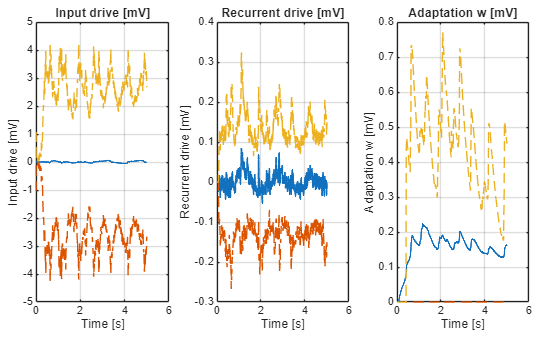

[SPIKING] Displayed spiking diagnostics without saving files. To save files, pass 'save_files', true.



%% ---------------- Spiking Dynamics Diagnostics ----------------
% These diagnostics replay the saved trained network through the CPU reference
% to produce spike rasters, firing-rate summaries, ISI histograms, voltage traces,
% input/recurrent/adaptation current summaries. By default they display inline only.
diag_opts = struct();
diag_opts.model_file = model_file;
diag_opts.output_dir = diag_dir;
diag_opts.save_files = save_diagnostic_files;
diag_opts.max_samples = 8;
diag = snn_primary_api('spike_diagnostics_dynamics', 'dynamical_systems', 'cpu', diag_opts);

fprintf('Test spiking active neurons: %.2f%%%% (%d/%d); silent neurons: %.2f%%%% (%d/%d).\n', ...
    diag.active_neuron_percent, diag.active_neuron_count, diag.n_neurons, ...
    diag.silent_neuron_percent, diag.silent_neuron_count, diag.n_neurons);

Test spiking active neurons: 45.52%% (2731/6000); silent neurons: 54.48%% (3269/6000).


fprintf('Mean per-sample active neurons: %.2f%%%%; silent neurons: %.2f%%%%.\n', ...
    mean(diag.active_percent_by_sample), mean(diag.silent_percent_by_sample));

Mean per-sample active neurons: 45.52%%; silent neurons: 54.48%%.


fprintf('Loaded trained network from:\n%s\n', model_file);

Loaded trained network from:
C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\models\dynamical_systems_vanderpol_full_rank6k_gpu_primary_seed001.mat


fprintf('Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.\n');

Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.


disp(result.test);

                wasserstein_distance: 0.0210
          wasserstein_distance_by_ic: [5×1 single]
                             x0_list: [2×5 single]
                  test_x0_norm_by_ic: {5×1 cell}
              truth_diagnostic_by_ic: {5×1 cell}
       truth_simulation_failed_by_ic: [5×1 logical]
                 closed_loop_ic_seed: 123
            closed_loop_test_ic_seed: 123
               closed_loop_ic_jitter: 0.0100
             closed_loop_warmup_time: 5
               closed_loop_test_time: 50
            closed_loop_warmup_steps: 5000
    closed_loop_truth_initialization: 'network_terminal_warmup_state'
                           pred_norm: [50000×2 single]
                           true_norm: [50000×2 single]
                     pred_norm_by_ic: {5×1 cell}
                     true_norm_by_ic: {5×1 cell}
                n_initial_conditions: 5
                            gpu_bias: [6000×1 single]

